# Plot 3-D Parametric Functions

`fplot3` plots the parametric curve defined by $x=f\left(t\right)$, $y=g\left(t\right)$, and $z=h\left(t\right)$ over the default interval of time $t$.

## Define Multivariable Function

Create three anonymous functions as $x\left(t\right)=e^{\frac{-t}{10}} \;\sin \left(5t\right)$, $y\left(t\right)=e^{\frac{-t}{10}} \;\cos \left(5t\right)$, and $z\left(t\right)=t$

xt = @(t) exp(-t/10).*sin(5*t);
yt = @(t) exp(-t/10).*cos(5*t);
zt = @(t) t;

## Create a Basic Function Plot 

Plot the parametric curve defined by the functions with `fplot3` over the default time interval $t=\left\lbrack -5,\;5\right\rbrack$

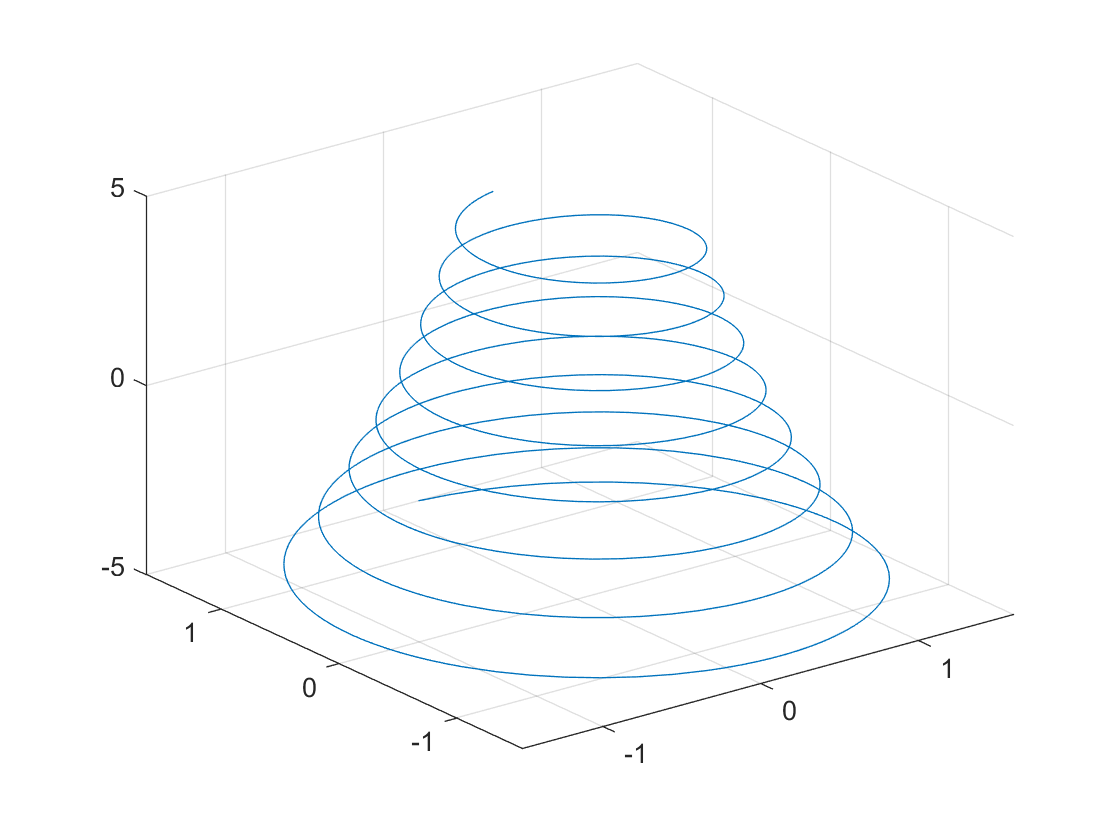

fplot3(xt,yt,zt)

## Customizations

### Define Time Span of Function Plot

Specify a time range $t=\left\lbrack -10,10\right\rbrack$ as an input to the `fplot3` function

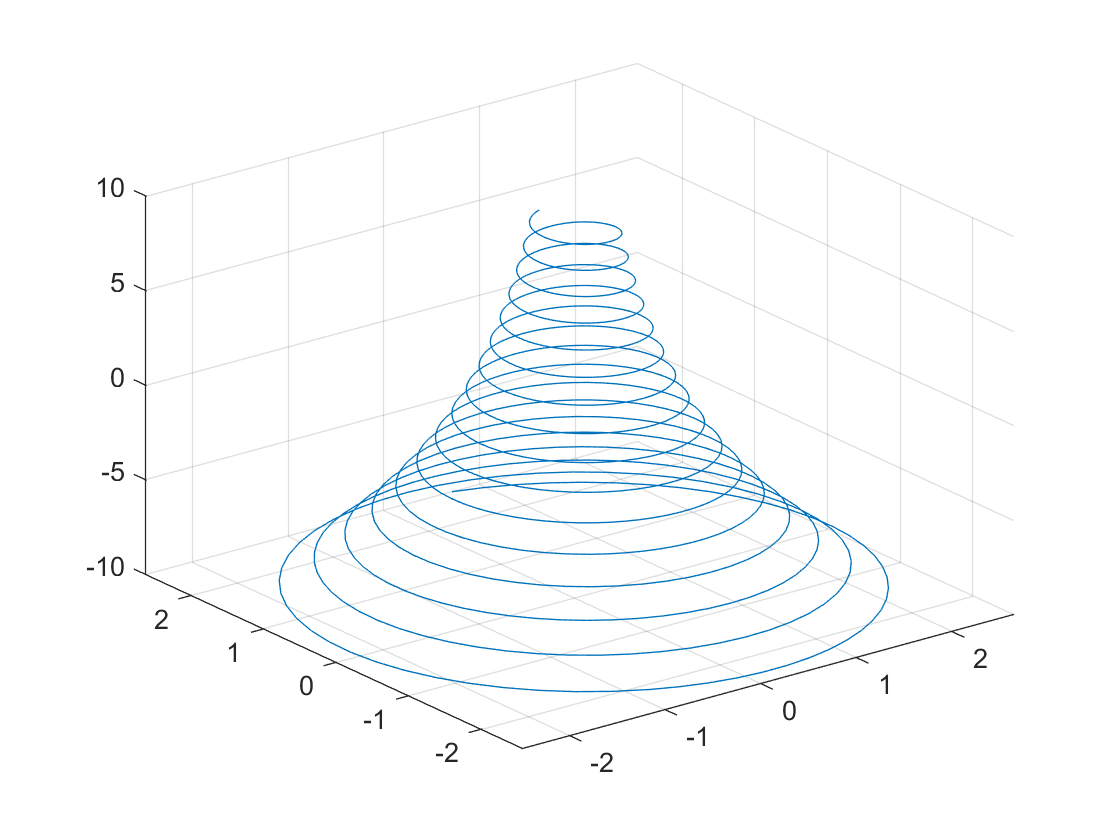

fplot3(xt,yt,zt,[-10 10])

### Plot Custom Peicewise Function 

Plot the same 3-D parametric curve three times over different intervals of the parameter. For the first interval, use a line width of 2 points. For the second, specify a dashed red line style with circle markers. For the third, specify a cyan, dash-dotted line style with asterisk markers.

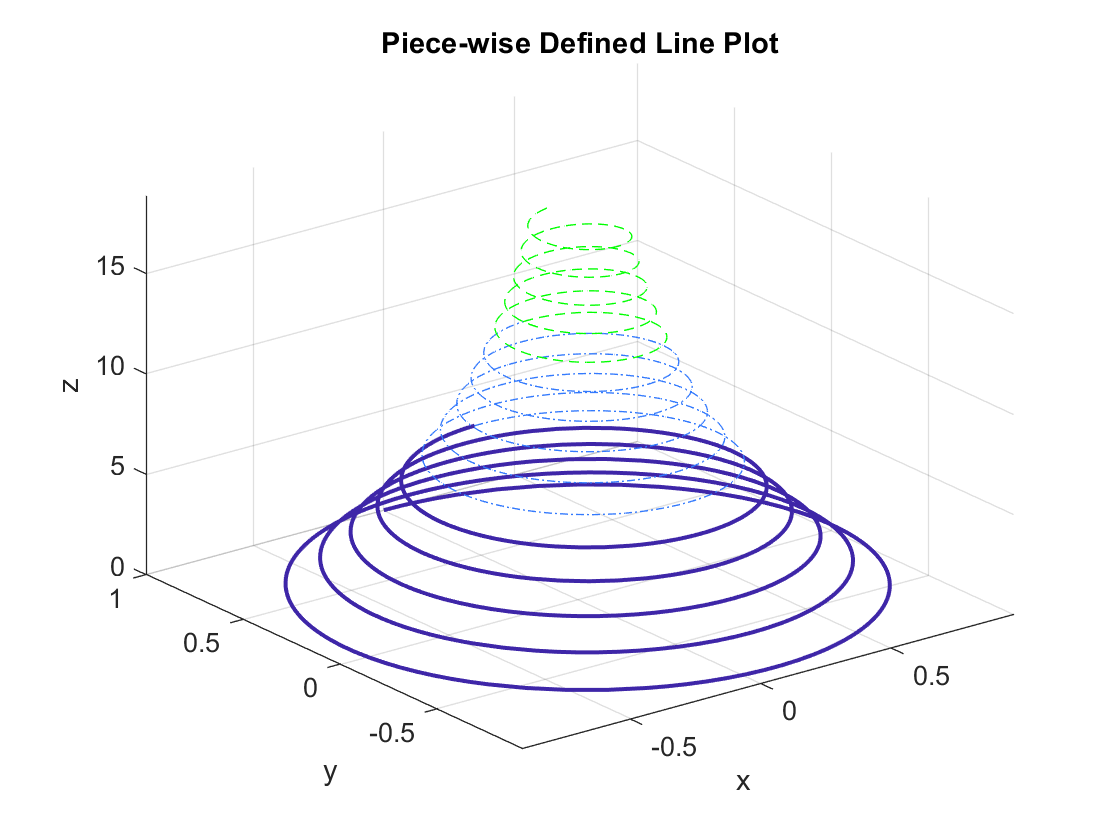

fp1 = fplot3(xt, yt, zt, [0 2*pi],...
    "color", [0.2422, 0.1504, 0.6603],...   % Specify line color as RGB triplet
    "LineWidth", 1.5);                      % Specify line thickness
hold on
fp2 = fplot3(xt, yt, zt, [2*pi 4*pi],...
    "color", [0.2021, 0.4788, 0.9911],...
    "LineStyle","-.");                      % Specify line style appearance
fp3 = fplot3(xt, yt, zt, [4*pi 6*pi],...
    "color", 'g',...                        % Specify line color as 'green'
    "LineStyle",'--');

title("Piece-wise Defined Line Plot")
xlabel('x')
ylabel('y')
zlabel('z')

## Additional Information

### Get All Fplot3 Properties

Graphics objects in MATLAB have many properties. To see all the properties of a fplot3, uncomment the following code

% get(fp1)

### Documentation

Follow the link below to go to the documentation page to learn about the plot type in detail.

[fplot3](https://www.mathworks.com/help/matlab/ref/fplot3.html)